
$$m_i *\frac{d x_i }{{\textrm{dt}} }=-\eta_i v_i -k_i x_i -k_{\textrm{ij}} \left(x_i -x_j \right)+F_i \left(t\right)$$


para cada partícula iii, donde:

- $\eta_i v_i$ representa un **término de amortiguamiento** (si está presente).

- $k_i x_i$ es el término restaurador del **resorte anclado a un punto fijo**.

- $k_{\textrm{ij}} \left(x_i -x_j \right)$ representa la **fuerza entre partículas vecinas**.

- $F_i \left(t\right)$ es una **fuerza externa**, en algunos casos sinusoidal.

Simulación con v1(0) = 10


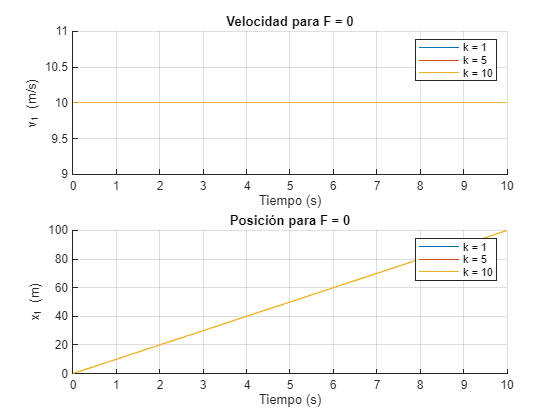

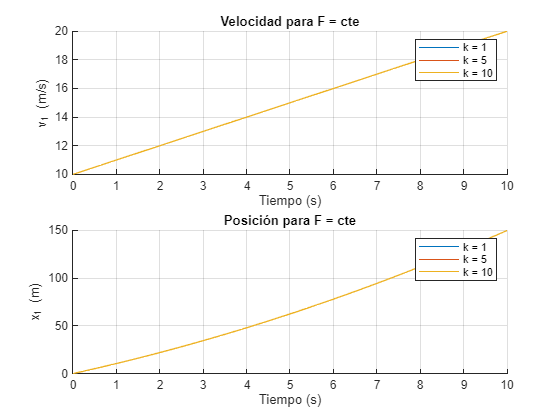

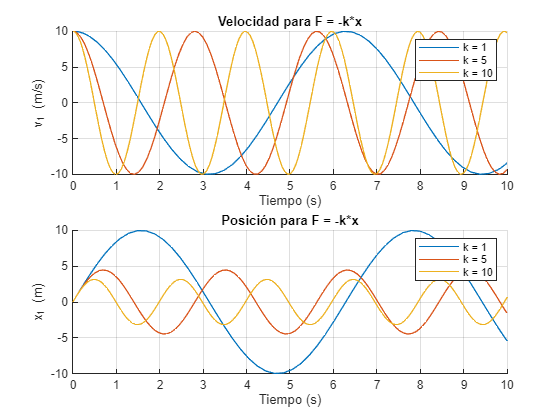

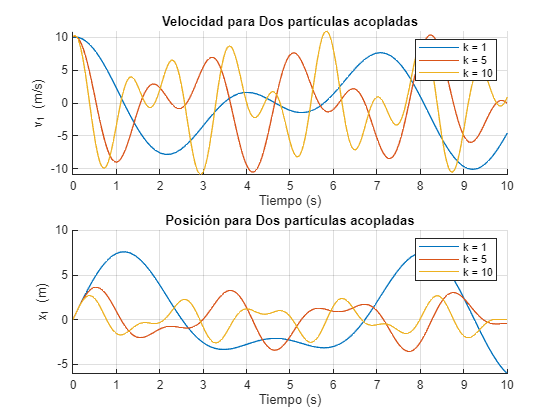

function newtons_third_law_positions(k_values, tspan, y0)
    % Escenarios de fuerzas
    scenarios = {@(t, y, k) force_zero(t, y), ...
                 @(t, y, k) force_constant(t, y), ...
                 @(t, y, k) force_spring(t, y, k), ...
                 @(t, y, k) force_coupled(t, y, k)};
    
    scenario_labels = {'F = 0', 'F = cte', 'F = -k*x', 'Dos partículas acopladas'};

    % === NUEVA ESTRUCTURA DE GRÁFICAS ===
    for s = 1:length(scenarios)
        figure;

        % Subplot 1: Velocidad de x1
        subplot(2, 1, 1); hold on;
        for k = k_values
            [t, Y] = ode45(@(t, y) scenarios{s}(t, y, k), tspan, y0);
            plot(t, Y(:, 2), 'DisplayName', ['k = ' num2str(k)]);
        end
        title(['Velocidad para ' scenario_labels{s}]);
        xlabel('Tiempo (s)');
        ylabel('v_1 (m/s)');
        legend show;
        grid on;

        % Subplot 2: Posición de x1
        subplot(2, 1, 2); hold on;
        for k = k_values
            [t, Y] = ode45(@(t, y) scenarios{s}(t, y, k), tspan, y0);
            plot(t, Y(:, 1), 'DisplayName', ['k = ' num2str(k)]);
        end
        title(['Posición para ' scenario_labels{s}]);
        xlabel('Tiempo (s)');
        ylabel('x_1 (m)');
        legend show;
        grid on;
    end
end



%% Definir funciones de fuerza para cada escenario
function dydt = force_zero(~, y)
    % F = 0 -> Movimiento con velocidad constante (para ambas partículas)
    
    dydt = [y(2); 0; y(4); 0];
end

function dydt = force_constant(~, y)
    % F = cte -> Aceleración constante para ambas partículas
    F = 1; % Constante arbitraria
    dydt = [y(2); F; y(4); F];
end

function dydt = force_spring(~, y, k)
    % F = -k*x -> Oscilaciones tipo resorte (para una partícula)
    dydt = [y(2); -k * y(1); y(4); 0]; % Segunda partícula no afectada
end

function dydt = force_coupled(~, y, k)
    dydt = [y(2); -2*k*y(1) + k*y(3); 
            y(4); -2*k*y(3) + k*y(1)];
end
% --- Ejecutar el script con los parámetros adecuados ---
k_values = [1, 5, 10];   % Diferentes valores de k
tspan = [0 10];         % Tiempo de simulación

% Diferentes valores de velocidad inicial para v1(0), manteniendo v2(0) = 0
v1_initial_values = [10];

for v1_0 = v1_initial_values
    % Condiciones iniciales [x1(0), v1(0), x2(0), v2(0)]
    y0 = [0; v1_0; 1; 0];  % Se actualiza v1(0) en cada iteración

    % Ejecutar la simulación
    fprintf('Simulación con v1(0) = %d\n', v1_0);
    newtons_third_law_positions(k_values, tspan, y0);
end

Se comprueba que a menor constante elástica el diagrama de fases tienda a ser más caótico, pero esto esto se debe a la restricción de tiempo que se ha instaurado. Si en vez de 10 segundos se compilará en un tiempo mayor, se obtendría un diagrama de fases cerrado para cualquier constante elástica. El tiempo también influye en la primera iteración, con velocidad cero, puesto que en el diagrama de fases no se distingue entre una constante elastica y otra, debido a que con un tiempo tan pequeño de compilación, no se llega a apreciar las diferencias entre las constantes elásticas.

Simulación con v1(0) = 10


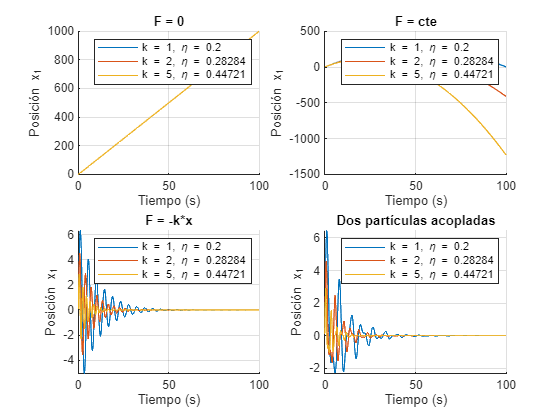

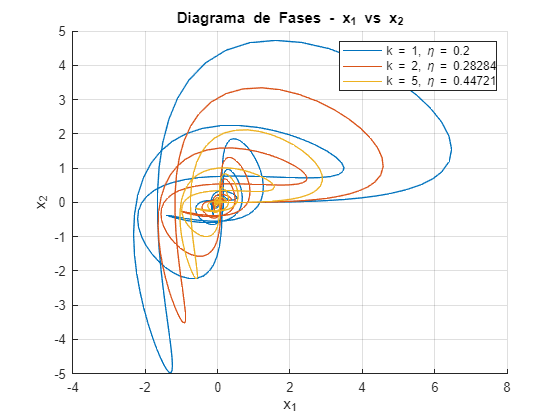

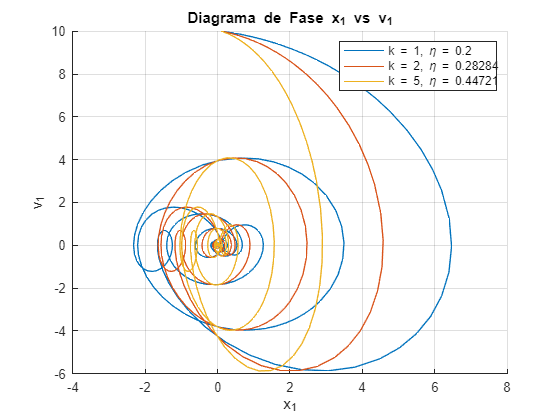

function newtons_third_law_positions2(k_values, eta_values, tspan, y0, show_legend)
    % Asegurar que los vectores k y eta son del mismo tamaño
    if length(k_values) ~= length(eta_values)
        error('Los vectores k_values y eta_values deben tener la misma longitud.');
    end

    % Escenarios de fuerzas con amortiguamiento
    scenarios = {@(t, y, k, eta) force_zero2(t, y, eta), ...
                 @(t, y, k, eta) force_constant2(t, y, eta), ...
                 @(t, y, k, eta) force_spring2(t, y, k, eta), ...
                 @(t, y, k, eta) force_coupled2(t, y, k, eta)};

    scenario_labels = {'F = 0', 'F = cte', 'F = -k*x', 'Dos partículas acopladas'};

    % Gráficas para cada escenario usando pares (k, eta)
    figure;
    for s = 1:length(scenarios)
        subplot(2, 2, s);
        hold on;
        for i = 1:length(k_values)
            k = k_values(i);
            eta = eta_values(i);
            [t, Y] = ode45(@(t, y) scenarios{s}(t, y, k, eta), tspan, y0);
            plot(t, Y(:, 1), 'DisplayName', ['k = ' num2str(k) ', \eta = ' num2str(eta)]);
        end
        title(scenario_labels{s});
        xlabel('Tiempo (s)');
        ylabel('Posición x_1');
        legend show;
        grid on;
    end

    % Diagrama de fases usando pares (k, eta)
    figure;
    hold on;
    for i = 1:length(k_values)
        k = k_values(i);
        eta = eta_values(i);
        [t, Y] = ode45(@(t, y) force_coupled2(t, y, k, eta), tspan, y0);
        plot(Y(:, 1), Y(:, 3), 'DisplayName', ['k = ' num2str(k) ', \eta = ' num2str(eta)]);
    end
    title('Diagrama de Fases - x_1 vs x_2');
    xlabel('x_1');
    ylabel('x_2');
    legend show;
    grid on;

    % === NUEVA FIGURA: Posición vs Velocidad de x_1 ===
    figure;
    hold on;
    for i = 1:length(k_values)
        k = k_values(i);
        eta = eta_values(i);
        [t, Y] = ode45(@(t, y) force_coupled2(t, y, k, eta), tspan, y0);
        plot(Y(:, 1), Y(:, 2), 'DisplayName', ['k = ' num2str(k) ', \eta = ' num2str(eta)]);
    end
    title('Diagrama de Fase x_1 vs v_1');
    xlabel('x_1');
    ylabel('v_1');
    legend show;
    grid on;
end



%% **Definir funciones de fuerza con amortiguamiento**
function dydt = force_zero2(~, y, n)
    dydt = [y(2); 0; 
            y(4); -n * y(4)];
end

function dydt = force_constant2(~, y, n)
    
    dydt = [y(2); -n;   % x1: dx1/dt = v1, dv1/dt = -n
            y(4); -n];  % x2: dx2/dt = v2, dv2/dt = -n
end



function dydt = force_spring2(~, y, k, n)
    dydt = [y(2); -2*k * y(1) - n * y(2);  
            y(4); -2*k * y(3) + k*y(1) - n * y(4)];
end

function dydt = force_coupled2(~, y, k, n)
    dydt = [y(2); -2*k * y(1) + k*y(3) - n * y(2); 
            y(4); -2*k * y(3) + k*y(1) - n * y(4)];
end

% --- Ejecutar el script con los parámetros adecuados ---
zeta_sub = 0.1;
k_values = [1, 2, 5];
n_values = 2 * zeta_sub * sqrt(k_values); 
tspan = [0, 100];  % Asegurar que estamos usando el tiempo extendido
v1_initial_values = [10];

for v1_0 = v1_initial_values
    y0 = [0.1; v1_0; 0; 0];  

    show_legend = (v1_0 == 0);

    fprintf('Simulación con v1(0) = %d\n', v1_0);
    newtons_third_law_positions2(k_values, n_values, tspan, y0, show_legend);
end

Con este modelo se aprecia como, con un modelo amortiguado, para los escenarios de acoplamiento las particulas tienen a cero con el paso del tiempo. La diferencia entre el escenario de una partícula y el modelo dos partículas acopladas radica en que a medida que se van acoplando más partículas, el modelo se va haciendo mas caótico puestpo que tiene más perturbaciones, aunque el modelo siga tendiendo a cero. 

Se aprecia una diferencia importante entre las variaciones entre la viscosidad y la elasticidad, como la elasticidad es mas influyente en la ecuación debido a que hay mas teminos dependientes de esta que de la viscosidad, cuanto mayor sea la constante elástica antes convergerá al punto de equilibrio del reposo y este proceso será más rápido que cuando varia la constante de viscosidad.

Simulación con v1(0) = 10


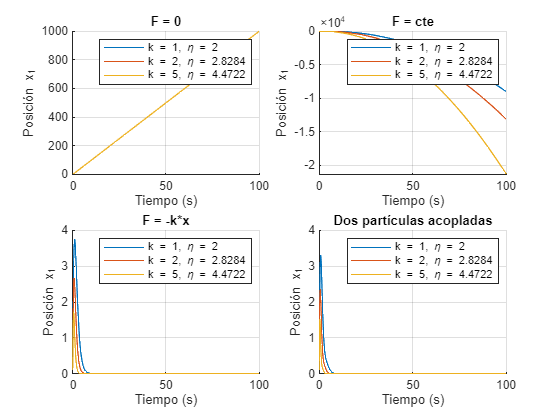

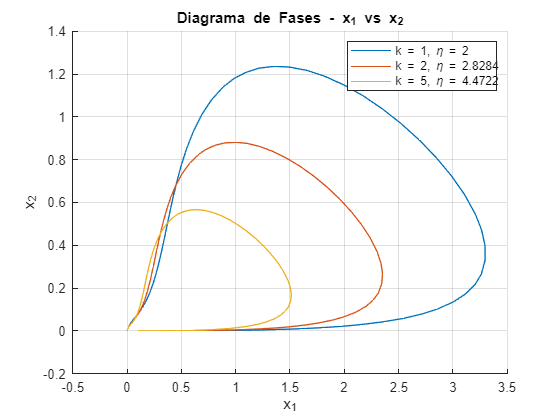

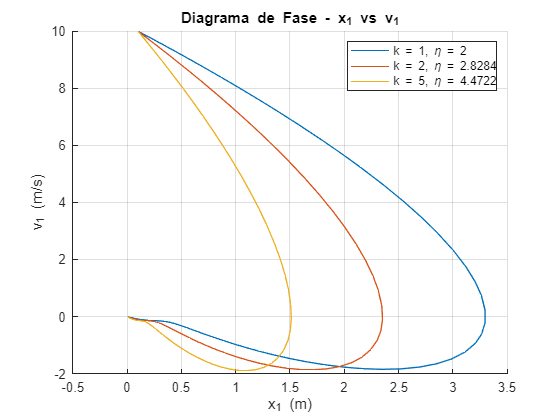

function newtons_third_law_positions3(k_values, eta_values, tspan, y0, show_legend)
    % Asegurar que los vectores k y eta son del mismo tamaño
    if length(k_values) ~= length(eta_values)
        error('Los vectores k_values y eta_values deben tener la misma longitud.');
    end

    % Escenarios de fuerzas con amortiguamiento
    scenarios = {@(t, y, k, eta) force_zero3(t, y, eta), ...
                 @(t, y, k, eta) force_constant3(t, y, eta), ...
                 @(t, y, k, eta) force_spring3(t, y, k, eta), ...
                 @(t, y, k, eta) force_coupled3(t, y, k, eta)};

    scenario_labels = {'F = 0', 'F = cte', 'F = -k*x', 'Dos partículas acopladas'};

    % Gráficas para cada escenario usando pares (k, eta)
    figure;
    for s = 1:length(scenarios)
        subplot(2, 2, s);
        hold on;
        for i = 1:length(k_values)
            k = k_values(i);
            eta = eta_values(i);
            [t, Y] = ode45(@(t, y) scenarios{s}(t, y, k, eta), tspan, y0);
            plot(t, Y(:, 1), 'DisplayName', ['k = ' num2str(k) ', \eta = ' num2str(eta)]);
        end
        title(scenario_labels{s});
        xlabel('Tiempo (s)');
        ylabel('Posición x_1');
        legend show;
        grid on;
    end

    % Diagrama de fase x1 vs x2
    figure;
    hold on;
    for i = 1:length(k_values)
        k = k_values(i);
        eta = eta_values(i);
        [t, Y] = ode45(@(t, y) force_coupled3(t, y, k, eta), tspan, y0);
        plot(Y(:, 1), Y(:, 3), 'DisplayName', ['k = ' num2str(k) ', \eta = ' num2str(eta)]);
    end
    title('Diagrama de Fases - x_1 vs x_2');
    xlabel('x_1');
    ylabel('x_2');
    legend show;
    grid on;

    % Diagrama de fase x1 vs v1 (nuevo gráfico)
    figure;
    hold on;
    for i = 1:length(k_values)
        k = k_values(i);
        eta = eta_values(i);
        [t, Y] = ode45(@(t, y) force_coupled3(t, y, k, eta), tspan, y0);
        plot(Y(:, 1), Y(:, 2), 'DisplayName', ['k = ' num2str(k) ', \eta = ' num2str(eta)]);
    end
    title('Diagrama de Fase - x_1 vs v_1');
    xlabel('x_1 (m)');
    ylabel('v_1 (m/s)');
    legend show;
    grid on;
end

%% **Corrección: Definir funciones para que devuelvan un vector de 4 elementos**
function dydt = force_zero3(~, y, eta)
    % F = 0 -> Movimiento rectilíneo uniforme (sin aceleración)
    dydt = [y(2); 0;  % dx/dt = v, dv/dt = 0 (velocidad constante)
            y(4); 0];    % Se agregan ceros para mantener el tamaño 4
end

function dydt = force_constant3(~, y, eta)
    % F = cte -> Aceleración constante (dv/dt = F/eta)
      % Definimos la fuerza arbitraria constante
    dydt = [y(2); -eta;  % dx/dt = v, dx/dt = F/eta
            y(4); 0];  % Se agregan ceros para mantener el tamaño 4
end

function dydt = force_spring3(~, y, k, eta)
    % F = -k*x - eta * v -> Oscilador amortiguado correctamente implementado
    dydt = [y(2);  % dx/dt = v
        -k*y(1) - eta*y(2);
        y(4);
        -k*y(3) - eta*y(4)];

end

function dydt = force_coupled3(~, y, k, eta)
    % Dos partículas acopladas sin aceleración y sin fuerzas externas.
    dydt = [y(2);
        -k*(2*y(1) - y(3)) - eta*y(2);
        y(4);
        -k*(2*y(3) - y(1)) - eta*y(4)];                                   
end



% --- Ejecutar el script con los parámetros adecuados ---
zeta_sub = 1.000005;
k_values = [1, 2, 5];
n_values = 2 * zeta_sub * sqrt(k_values);    
tspan = [0 100];  % Se extiende el tiempo para capturar mejor la dinámica
v1_initial_values = [10];

for v1_0 = v1_initial_values
    y0 = [0.1; v1_0; 0; 0];  % Introducir una pequeña diferencia en posición

    show_legend = (v1_0 == 0);

    fprintf('Simulación con v1(0) = %d\n', v1_0);
    newtons_third_law_positions3(k_values, n_values, tspan, y0, show_legend);
end

Se

Simulación con v1(0) = 10


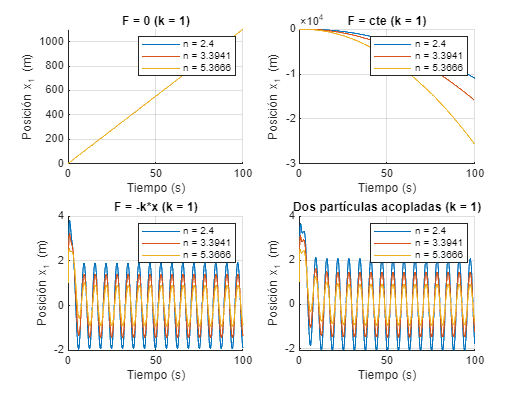

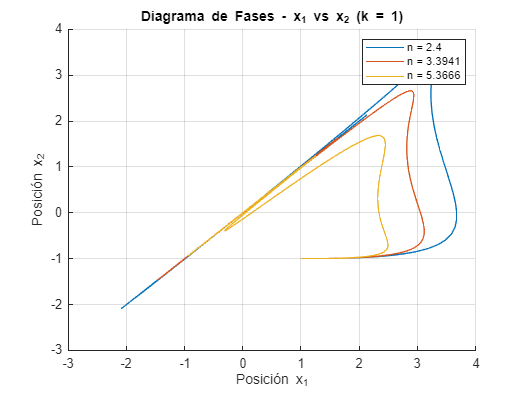

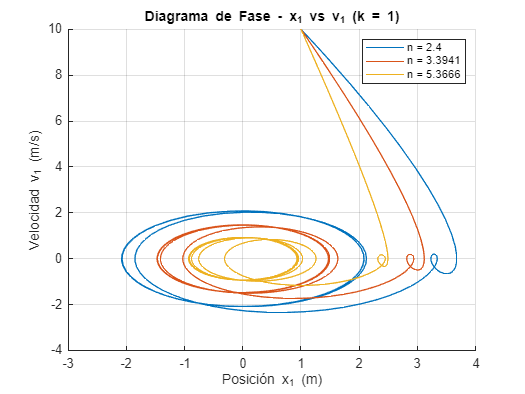

function newtons_third_law_positions4(k_values, n_values, tspan, y0, show_legend)
    % Escenarios de fuerzas con amortiguamiento y fuerza oscilatoria
    scenarios = {@(t, y, k, n) force_zero4(t, y, k, n), ...
                 @(t, y, k, n) force_constant4(t, y, k, n), ...
                 @(t, y, k, n) force_spring4(t, y, k, n), ...
                 @(t, y, k, n) force_coupled4(t, y, k, n)};
    scenario_labels = {'F = 0', 'F = cte', 'F = -k*x', 'Dos partículas acopladas'};

    % Gráficas para k = 1 con distintos valores de eta (n)
    figure;
    for s = 1:length(scenarios)
        subplot(2, 2, s);
        hold on;
        for n = n_values
            [t, Y] = ode45(@(t, y) scenarios{s}(t, y, 1, n), tspan, y0);
            plot(t, Y(:, 1), 'DisplayName', ['n = ' num2str(n)]);
        end
        title([scenario_labels{s} ' (k = 1)']);
        xlabel('Tiempo (s)');
        ylabel('Posición x_1 (m)');
        legend show;
        grid on;
    end

    % Diagrama de fase x1 vs x2 (solo para el acoplado)
    figure;
    hold on;
    for n = n_values
        [t, Y] = ode45(@(t, y) force_coupled4(t, y, 1, n), tspan, y0);
        plot(Y(:, 1), Y(:, 3), 'DisplayName', ['n = ' num2str(n)]);
    end
    title('Diagrama de Fases - x_1 vs x_2 (k = 1)');
    xlabel('Posición x_1');
    ylabel('Posición x_2');
    legend show;
    grid on;

    % NUEVO: Diagrama de fase x1 vs v1 (para sistema acoplado)
    figure;
    hold on;
    for n = n_values
        [t, Y] = ode45(@(t, y) force_coupled4(t, y, 1, n), tspan, y0);
        plot(Y(:, 1), Y(:, 2), 'DisplayName', ['n = ' num2str(n)]);
    end
    title('Diagrama de Fase - x_1 vs v_1 (k = 1)');
    xlabel('Posición x_1 (m)');
    ylabel('Velocidad v_1 (m/s)');
    legend show;
    grid on;
end

%% **Definir funciones de fuerza corregidas**
function dydt = force_zero4(t, y, ~, n)
    % F = 0, pero con amortiguamiento oscilatorio corregido
    f_t = sin(t);
    dydt = [y(2); f_t;
            y(4); -n * y(4) + f_t];
end

function dydt = force_constant4(t, y, ~, n)
    % F = constante con amortiguamiento oscilatorio corregido
    F = 1;  % Constante arbitraria
    f_t = sin(t);
    dydt = [y(2); - n + f_t;
            y(4); F - n * y(4) + f_t];
end

function dydt = force_spring4(t, y, k, n)
    % Oscilador amortiguado con fuerza externa sinusoidal corregido
    f_t = 5 * sin(t);
    dydt = [y(2); -2*k * y(1) - n * y(2) + f_t;
            y(4); -k * y(3) - n * y(4) + f_t];
end

function dydt = force_coupled4(t, y, k, n)
    % Dos partículas acopladas con oscilaciones externas corregido
    f_t = 5 * sin(t);
    dydt = [y(2); -2*k * y(1) + k * y(3) - n * y(2) + f_t;  
            y(4); -2*k * y(3) + k * y(1) - n * y(4) + f_t];
end

%% **Ejecución del script con parámetros adecuados**
zeta_sub = 1.2;
k_values = [1, 2, 5];
n_values = 2 * zeta_sub * sqrt(k_values);     % Diferentes valores de n
tspan = [0 100];         % Se aumenta el tiempo de simulación

% Diferentes valores de velocidad inicial para v1(0), manteniendo v2(0) = 0
v1_initial_values = [10];

for v1_0 = v1_initial_values
    y0 = [1; v1_0; -1; 0];  % Pequeña diferencia inicial en posición
    show_legend = (v1_0 == 0);

    fprintf('Simulación con v1(0) = %d\n', v1_0);
    newtons_third_law_positions4(k_values, n_values, tspan, y0, show_legend);
end

La inclusión de un forzante sinusoidal se plasma en el modelo añadiendo complejidad en comparación con los anteriores sistemas ya simulados, se observa como la respuesta depende fuertemente de los valores del amortiguamento y la constante de acoplamiento. Aún en este modelo se ve clara la diferencia entre las distintas velocidades, a medida que la velocidad aumenta las curvaturas de las oscilaciones en el diagrama de fases se hacen mayores, siendo estas dos directamente proporcionales. 

Además se observa como a medida que crece tanto la viscosidad como la constante de elasticidad, las oscilaciones son menores. Si la constante de elasticidad disminuye la posición de la particula oscila con una amplitud mayor y lo mismo pasa con la viscosidad. 